### Openning WVM output

%ncfile = NetCDFFile('run10FinalLeticia.nc');
ncfile = NetCDFFile('run18_icR_iner07_tide014_lat32_geo0065_N0052_boussinesq_res512.nc');

% initialize wvt from file
wvt = WVTransform.waveVortexTransformFromFile(ncfile.path, iTime=Inf);
%t = ncfile.readVariables('t');

E_model= wvt.transformToRadialWavenumber( wvt.Apm_TE_factor .* (abs(wvt.Ap).^2 + abs(wvt.Am).^2) );
E_model=E_model./(wvt.kRadial(2)-wvt.kRadial(1));
j=wvt.j;
kRadial=wvt.kRadial;

kIndices = kRadial<wvt.forcingWithName("adaptive damping").k_damp;
jIndices = j > 0 & j < wvt.forcingWithName("adaptive damping").j_damp;
S_wvt = E_model(jIndices,kIndices);
j = j(jIndices);
k = kRadial(kIndices);

dk = (k(2)-k(1));
sum(S_wvt(:))*dk

ans = 4.1405

### Initialize the toolbox

%Stratification 1 - Exponential
% f0=2*7.2921e-5*sind(latitude);
latExp=33;
L_gm = 1300;
N0 = 3*2*pi/3600;
N2funcExp = @(z) N0*N0*exp(2*z/L_gm);
LzExp=4000;
tic
igw = InternalGravityWaveSpectrum(N2funcExp,LzExp,nModes=56,nK=200,latitude=latExp);
toc

Elapsed time is 329.130279 seconds.


### Distributing energy

igw_GM= igw.assignEnergySpectrum("gm");
igw_gen=igw.assignEnergySpectrum("general");

### SGM + M2 + fM2

model_IGW = igw.gmSpectrum(j_star=10);
model_M2 = igw.tidalSpectrum(A=25,c=1e-5);
model_fM2 = igw.fM2Spectrum(A=20,c=1e-5);
S_GMTide= @(k,jInd) model_IGW(k,jInd) + model_M2(k,jInd) +model_fM2(k,jInd);

%%
sum(S_wvt(:)*(k(2)-k(1)))

ans = 4.1405

S_GMTidejk = zeros(length(j),length(k));
for indj = 1:length(j)
    for indk = 1:length(k)
        S_GMTidejk(indj,indk) = S_GMTide(k(indk)+(dk/1.9),j(indj));
    end
end
nansum(S_GMTidejk(:)*(k(2)-k(1)))

ans = 3.3869

### Sgen + M2 + fM2

model_IGW = igw.generalSpectrum(j_star=9,slope_j=2,slope_k=1.6,A=0.84);
model_M2 = igw.tidalSpectrum(A=25,c=1e-5);
model_fM2 = igw.fM2Spectrum(A=20,c=1e-5);
model_f = igw.fSpectrum(A=100,c=1e-5);
S_genTide = @(k,jInd) model_IGW(k,jInd) + model_M2(k,jInd) + model_fM2(k,jInd)+ model_f(k,jInd);
%S_genTide = @(k,jInd) model_M2(k,jInd) + model_fM2(k,jInd)+ model_f(k,jInd);

%%
sum(S_wvt(:)*(k(2)-k(1)))

ans = 4.1405

S_genTidejk = zeros(length(j),length(k));
for indj = 1:length(j)
    for indk = 1:length(k)
        S_genTidejk(indj,indk) = S_genTide(k(indk)+(dk/1.9),j(indj));
    end
end
nansum(S_genTidejk(:)*(k(2)-k(1)))

ans = 4.1583

### Plot panels

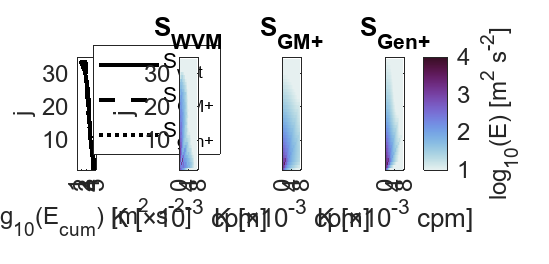

figure
tiledlayout(1,4, 'TileSpacing', 'compact', 'Padding', 'compact')

%% Painel 1 - Energy acumulada por modo vertical
nexttile
plot(log10(sum(S_wvt,2)), j, 'k-', 'LineWidth', 2)
hold on
plot(log10(nansum(S_GMTidejk,2)), j, 'k--', 'LineWidth', 2)
plot(log10(nansum(S_genTidejk,2)), j, 'k:', 'LineWidth', 2)
ylabel('j')
xlabel('log_{10}(E_{cum}) [m^2 s^{-2}]')
ylim([1 35])
xlim([0.9 5.1])
%set(gca, 'XScale', 'log')

legend('S_{wvt}','S_{GM+}','S_{gen+}','Location', 'southwest')
ax = gca;
ax.FontSize = 12;               
ax.XLabel.FontSize = 12;        
ax.YLabel.FontSize = 12; 

ax.XTick = [1 2 3 4 5];      % true values
ax.XTickLabel = {'1','2','3','4','5'};   % custom labels


%xticks(logspace(log10(min(xlim)), log10(max(xlim)), 4)) % 6 ticks between limits

%% Painel 2 - WVM
nexttile
jpcolor(2*pi*k, j, log10(S_wvt))
clim([1 4])
title('S_{WVM}')
xlabel('K [×10^{-3} cpm]')
ylabel('j')
cmocean('dense')
xlim([0 0.0081])

ax = gca;
ax.FontSize = 12; 
ax.XTick = [0 0.004 0.008];      % true values
ax.XTickLabel = {'0','4','8'};   % custom labels

%% Painel 3 - GM+
nexttile
jpcolor(2*pi*k, j, log10(S_GMTidejk))
clim([1 4])
title('S_{GM+}')
xlabel('K [×10^{-3} cpm]')
set(gca, 'YTickLabel', []);
cmocean('dense')
xlim([0 0.0081])

ax = gca;
ax.FontSize = 12; 
ax.XTick = [0 0.004 0.008];
ax.XTickLabel = {'0','4','8'};

%% Painel 4 - Gen+
nexttile
jpcolor(2*pi*k, j, log10(S_genTidejk))
clim([1 4])
title('S_{Gen+}')
xlabel('K [×10^{-3} cpm]')
set(gca, 'YTickLabel', []);
cmocean('dense')

cb = colorbar; 
ylabel(cb, 'log_{10}(E) [m^2 s^{-2}]') 
cb.FontSize = 12;
xlim([0 0.0081])

ax = gca;
ax.FontSize = 12; 
ax.XTick = [0 0.004 0.008];
ax.XTickLabel = {'0','4','8'};

%% General figure size
set(gcf, 'Units', 'centimeters', 'Position', [5,5, 25, 12]);

% Salvar com tamanho e qualidade especificados

exportgraphics(gcf, ['SGen_Inertial', '.png'], 'Resolution', 300);

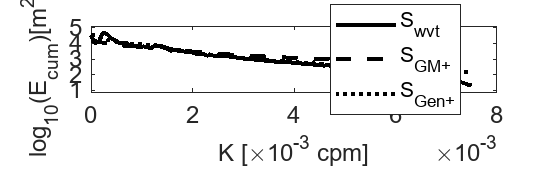

figure

% Painel 1 - Energy acumulada por modo vertical
nexttile
plot(2*pi*k,log10(sum(S_wvt,1)),LineStyle="-",LineWidth=2,Color="k")
hold on
plot(2*pi*k,log10(nansum(S_GMTidejk,1)),LineStyle="--",LineWidth=2,Color="k")
plot(2*pi*k,log10(nansum(S_genTidejk,1)),LineStyle=":",LineWidth=2,Color="k")
xlabel('K [\times10^{-3} cpm]')
ylabel('log_{10}(E_{cum})[m^2s^{-2}]')
%set(gca, 'YScale', 'log')
ylim([0.9 5.1])

legend('S_{wvt}','S_{GM+}','S_{Gen+}','Location', 'best')

ax = gca;
ax.FontSize = 12;               
ax.Title.FontSize = 14;        
ax.XLabel.FontSize = 12;        
ax.YLabel.FontSize = 12; 
ax.YTick = [1 2 3 4 5];      % true values
ax.YTickLabel = {'1','2','3','4','5'};   % custom labels


set(gcf, 'Units', 'centimeters', 'Position', [5,5, 18.75, 6.25]);

% Salvar com tamanho e qualidade especificados
exportgraphics(gcf, ['SGen_Inertical_Ecum_overK', '.png'], 'Resolution', 300);

### Plot Frequency spectrum 

omegaVector= linspace(min(igw.omega(:)),max(igw.omega(:)),500);
% omega_min = min(igw.omega(:));
% omega_max = max(igw.omega(:));
% omegaVector = logspace(log10(omega_min), log10(omega_max), 500);

%log space

figure(2)
z1=-511.8385;
energyAtFreq = igw_gen.energyAtFrequencies(z1, "TE", omegaVector=omegaVector, plot=0);
%omegaVector = igw.omegaVector;
freqCPD = (omegaVector)*(24*3600)/(2*pi);
loglog(freqCPD, energyAtFreq * 1000, 'LineWidth', 2);
xline(igw.f0*(24*3600)/(2*pi))
xline(1.4053e-4*(24*3600)/(2*pi))
xline(2.1996e-4*(24*3600)/(2*pi))

xlabel('Frequency [cycles/day]')
ylabel('TE')
%title('-400 m')


### Understanding the parameter space

paramList = [
    3, 1.7, 0.8, 2;   % (1,1)
    10, 1.7, 0.8, 2;  % (1,2)
    15, 1.7, 0.8, 2;  % (1,3)
    
    10, 1.0, 0.8, 2;  % (2,1)
    10, 1.7, 0.8, 2;  % (2,2)
    10, 4.0, 0.8, 2;  % (2,3)
    
    10, 1.7, 0.1, 2;  % (3,1)
    10, 1.7, 0.8, 2;  % (3,2)
    10, 1.7, 2.0, 2;  % (3,3)
    
    10, 1.7, 0.8, 1;  % (4,1)
    10, 1.7, 0.8, 2;  % (4,2)
    10, 1.7, 0.8, 4;  % (4,3)
];

% Crie uma figura com subplots organizados
figure;
tl=tiledlayout(4,3, 'Padding', 'compact', 'TileSpacing', 'compact');
title(tl, 'S_{Gen}',fontsize=16);

% Nomes dos parâmetros, só para referência
paramNames = ["j^*", "slope_{k}", "slope_j", "GM Amp"];

for idx = 1:size(paramList, 1)
    nexttile;
    
    params = paramList(idx,:);
    model_IGW = igw.generalSpectrum(j_star=params(1),slope_j=params(3),slope_k=params(2),A=params(4));  % função geradora do modelo
    %model_IGW = igw.gmSpectrum_free(j_star=params(1),slope_j=params(3),slope_k=params(2),A=params(4));
    % Executa a função que plota o modelo
    objectiveFunction(igw, model_IGW, k, j, S_wvt);
    
    % Determine qual parâmetro está variando nesta linha
    rowNum = ceil(idx / 3);
    colNum = mod(idx - 1, 3) + 1;
    
    % Pegue os 3 valores da linha correspondente
    startIdx = (rowNum - 1) * 3 + 1;
    lineParams = paramList(startIdx:startIdx+2, :);
    
    % Identifique qual coluna (parâmetro) está mudando
    varyingParamIdx = find(any(abs(diff(lineParams)) > 1e-8, 1));  % tolerância para float
    
    % Título simplificado com o valor da variável que muda
    title(sprintf('%s = %.3g', paramNames(varyingParamIdx), params(varyingParamIdx)));
end
